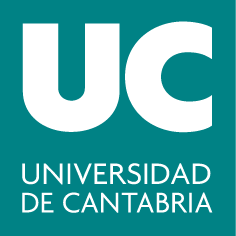

#### ***Grado en Ingeniería Química***

## **G320: Álgebra**

# **Práctica 9: Espacio euclídeo (II)**

*Rodrigo García Manzanas (rodrigo.manzanas@unican.es)*

*Valvanuz Fernández Quiruelas (valvanuz.fernandez@unican.es)*

**Objetivos**

- Resolución (aproximada) de sistemas incompatibles por mínimos cuadrados

- Ajuste a una nube de puntos

**Resolución (aproximada) de sistemas incompatibles por mínimos cuadrados**

Imaginemos el siguiente sistema de ecuaciones lineales:


$$\textstyle\left\{  \begin{array}{rcr}
			 x  -y & = & 1\\ 
			 y + z & = & 0\\
			 x +y+2z & = & -1\\  
		 \end{array}\right.$$


Es fácil comprobar que es incompatible (no tiene solución):

A = [1 -1 0; 0 1 1; 1 1 2];  % matriz de coeficientes
b = [1 0 -1]';  % vector de términos independientes
Aamp = [A b];  % matriz ampliada
[rank(A) rank(Aamp)]  % S.I.

Hemos visto que en estas circunstancias siempre es posible obtener una solución aproximada por mínimos cuadrados. Se trataría de sustituir el vector de términos indpendientes $\vec{b}$, para el cual no existe solución, por otro vector $\vec{c}$ para el cual el sistema sí tenga solución/soluciones. Este vector $\vec{c}$ será la proyección de $\vec{b}$ sobre el subespacio generado por las columnas de $A$. Para encontrar nuestro $\vec{c}$ tendremos que hallar en primer lugar una base de este subespacio, por lo que hay que comprobar si las columnas de $A$ son L.I.: 

rref(A)  % la tercera columna es combinación lineal de las dos primeras, que son L.I.

Ahora ya estamos en condiciones de calcular la matriz de proyección sobre el subespacio generado por las columnas de $A$, puesto que conocemos una base del mismo. A partir de esta base obtendremos la matriz de proyección que nos permitirá encontrar el vector $\vec{c}$ para el cual el sistema pasa a ser compatible.

P = A(:,1:2)*inv(A(:,1:2)'*A(:,1:2))*A(:,1:2)'  % matriz de proyección (me quedo
% únicamente las columnas de A que son L.I.)
c = P*b  % vector para el cual el sistema pasa a ser compatible. Es
% la proyección de b sobre el subespacio generado por las columnas de A
[rank(A), rank([A c])]  % S.C.I.

Nuestro nuevo sistema (el que resulta de sustituir $\vec{b}$ por $\vec{c}$) es compatible indeterminado (infinitas soluciones). Ya sabemos cómo resolver este tipo de sistemas:

syms x y z real
X = [x y z]';  % vector de incógnitas simbólicas
sol = solve(A*X == c, [x y])  % resuelvo en las incógnitas principales (columnas 
% pivotales de A)
sol_mc = [sol.x sol.y z]  % solución aproximada por mínimos cuadrados

Siempre es recomendable comprobar que la solución que hemos hallado es correcta:

% Compruebo que así sea para un valor cualquiera del parámetro z
A*subs(sol_mc, z, 2.365)' - c   % para z=2.365

Y en cualquier caso el error cuadrático cometido sería:

norm(c-b)^2  % error cuadrático 

Si las columnas de la matriz de coeficientes del sistema incompatible que trato de resolver son L.I., el proceso se simplifica, puesto que una vez que hallemos nuestro $\vec{c}$, nos quedará un S.C.D. con una única solución, que podríamos resolver directamente por medio del operador "\". De hecho, una vez sabemos que las columnas de la matriz de coeficientes son L.I. no haría falta ni siquiera calcular explícitamente $\vec{c}$, puesto que sabemos que la solución de mínimos cuadrados puede calcularse directamente como $(A^t A)^{-1}A^t\vec{b}$. Como ejemplo, en el siguiente sistema:


$$\textstyle\left\{  \begin{array}{rcr}
			 -x  + 4y & = & 15\\ 
			 y & = & 6\\
			 -y & = & 4\\  
			 x -2y & = & -5\\  
		 \end{array}\right.$$


A = [-1 4; 0 1; 0 -1; 1 -2];  % matriz de coeficientes
b = [15 6 4 -5]';  % vector de términos independientes
[rank(A) rank([A b])]  % S.I.
% Como las columnas de A son L.I. (rg(A)=2), podemos calcular
% directamente la solución (única) de mínimos cuadrados como:
sol_mc = inv(A'*A)*A'*b  

Acabamos de hallar que la solución de mínimos cuadrados es $x=-1, y=3$. Esto quiere decir que el vector $\vec{c}$ se puede expresar como combinación lineal de las columnas de $A$, siendo los coeficientes de dicha C.L. $-1$ y $3$.

**Ajuste a una nube de puntos**

Hemos visto que dada una nube de puntos, se puede ajustar por un tipo de función predefinida (polinómica, exponencial, etc.). Para ello habría que resolver el sistema que resulte de forzar a que nuestra función aproximadora pase por todos los puntos de la nube. Previsiblemente, este sistema será incompatible (no tendrá solución). Sin embargo, podremos buscar una solución aproximada por mínimos cuadrados. A modo de ejemplo, imaginemos que tenemos los siguientes datos experimentales relativos a la medida de una variable independiente, $x$, y otra dependiente, $y$

Para obtener un ajuste lineal (es decir, una recta $y=mx+n$), habría que resolver el sistema


$$\textstyle\left\{  \begin{array}{rcr}
			 2m  + n & = & 6\\ 
			 5m + n & = & 7.9\\
			 7m +n & = & 8.5\\  
		 \end{array}\right.$$


en el que las incógnitas serán $m$ y $n$ (coeficientes de la recta de ajuste). Lo resolvemos:

x0 = [2 5 7];  % coordenada x de los puntos de la nube
y0 = [6 7.9 8.5];  % coordenada y de los puntos de la nube
A = [x0', ones(length(x0), 1)]  % matriz de coeficientes del sistema a resolver
b = y0'  % vector de términos independientes del sistema a resolver
[rank(A) rank([A b])]  % S.I.

Las columnas de $A$ son L.I. ($rg(A)=2$), por lo que podemos calcular directamente la solución de mínimos cuadrados como:

sol_mc = inv(A'*A)*A'*b  % solución de mínimos cuadrados

El primer (segundo) elemento de esta solución será el coeficiente $m$ ($n$) de nuestro ajuste lineal. Por tanto, el polinomio aproximador buscado es $y=0.5105x+5.0842$.

Si en lugar de un polinomio aproximador de grado $1$ (una recta), quisiera uno de grado $2$ ($y=mx^2+nx+p$), tendría que resolver el siguiente sistema:


$$\textstyle\left\{  \begin{array}{rcr}
			 2^2m  + 2n +p& = & 6\\ 
			 5^2m + 5n +p& = & 7.9\\
			 7^2m +7n +p& = & 8.5\\  
		 \end{array}\right.$$


Donde mis incógnitas serán $m$, $n$ y $p$ (los coeficientes de la curva de ajuste). Lo resolvemos:

A = [x0.^2', x0', ones(length(x0), 1)]  % matriz de coeficientes (el 
% simbolo ".^" se utiliza para realizar la potenciación elemento a elemento)
b = y0'  % vector de términos independientes
[rank(A) rank([A b])]  % S.C.D.

Vemos que en este caso, el sistema es compatible determinado (existe solución exacta, y es única). Esto ocurre porque tenemos únicamente tres puntos en nuestra nube, por lo que, el número de ecuaciones y el de incógnitas se igualan. *En general, si tenemos una nube con *$n$* puntos, siempre podremos encontrar un polinomio interpolador de grado *$n-1$* que pase por todos ellos.* En nuestro caso, el polinomio de grado $2$ que buscamos vendrá dado por la solución (única) del sistema que hemos planteado:

sol = A\b  % S.C.D.

Se trata por tanto del polinomio $y=-0.0667x^2 + 1.1x + 4.0667$.

Por último, si quisiéramos un ajuste exponencial del tipo $y=me^{nx}$, podríamos tomar logaritmos a ambos lados de la expresión, quedándonos $ln(y)=ln(m)+nx$, que se convierte en un polinomio de grado $1$ (es decir, una ecuación lineal). Se trataría por tanto de resolver el sistema


$$\textstyle\left\{  \begin{array}{rcr}
			 2n  + ln(m) & = & ln(6)\\ 
			 5n + ln(m) & = & ln(7.9)\\
			 7n + ln(m) & = & ln(8.5)\\  
		 \end{array}\right.$$


en el que las incógnitas serán $n$ y $ln(m)$. A partir de ellas obtendremos los coeficientes de la función de ajuste buscada:

A = [x0', ones(length(x0), 1)]  % matriz de coeficientes
b = log(y0')  % vector de términos independientes (en MATLAB, el 
% logaritmo neperiano se calcula con la función "log")
[rank(A) rank([A b])]  % S.I.

Las columnas de $A$ son L.I. ($rg(A)=2$), por lo que puedo calcular directamente la solución de mínimos cuadrados como:

sol_mc = inv(A'*A)*A'*b  % solución de mínimos cuadrados

Por tanto, el coeficiente $n$ en nuestra función de ajuste sería $0.0714$, y el $m$ sería $e^{1.664}$. La exponencial que buscábamos será $y=5.29284e^{0.0714x}$.

Para el caso de ajustes polinómicos, MATLAB dispone de la función *polyfit, *que devuelve directamente los coeficientes del polinomio aproximador buscado. Podemos utilizarla para comprobar que los polinomios de orden $1$ y $2$ que hemos obtenido anteriormente son correctos:

% En la función polyfit, el tercer argumento de entrada hace referencia
% al grado del polinomio aproximador que queremos considerar
p1 = polyfit(x0, y0, 1)  % coeficientes de la RECTA de ajuste
% y = 0.5105x + 5.0842
p2 = polyfit(x0, y0, 2)  % coeficientes del POLINOMIO de ajuste DE ORDEN 2
% y=-0.0667x^2 + 1.1x + 4.0667

Del mismo modo, también podemos utilizar *polyfit* para comprobar que el ajuste exponencial al que habíamos llegado es correcto:

p3 = polyfit(x0, log(y0), 1)   % coeficientes del ajuste EXPONENCIAL
% y = exp(1.6664)*exp(0.0714x)

Una vez hemos obtenido los tres ajustes que buscábamos, podemos representar todos ellos en un mismo gráfico junto a la nube de puntos inicial, para lo cual utilizaremos las funciones *polyval* y *plot. polyval *permite evaluar un polinomio (definido por sus coeficientes) en un determinado punto (o puntos). Por ejemplo, podría interesarnos saber cuál sería el valor aproximado para $y$ cuando $x=7$ de acuerdo a la recta y al polinomio de ajuste de orden $2$ que hemos obtenido:

polyval(p1, 7)  % valor estimado por la RECTA de ajuste para 'y' cuando 'x=7'
polyval(p2, 7)  % valor estimado por el POLONIOMIO de ajuste DE ORDEN 2
% para 'y' cuando 'x=7'

Por su parte, la función *plot *se usa para representar pares de puntos *(x,y). *Por tanto, construiríamos el gráfico pedido del siguiente modo:

figure  % abro una nueva ventana gráfica
plot(x0, y0, 'ok')  % nube de puntos. El argumento opcional 'ob' indica 
% que quiero representar círculos (o) negros (k: blacK)

x = 0:0.01:10;  % doy valores a 'x' en el intervalo que quiero dibujar: [0, 10]

hold  on  % para seguir dibujando en la misma ventana gráfica
plot(x, polyval(p1, x), 'b')  % RECTA de ajuste, en azul (b: Blue)
plot(x, polyval(p2, x), 'r'),  % POLINOMIO de ajuste DE ORDEN 2, en rojo (r: Red)
plot(x, exp(p3(2))*exp(p3(1)*x), 'g')  % Función EXPONENCIAL de ajuste, 
% en verde (g: Green)

legend('nube', 'recta', 'polinom. orden 2', 'exponencial')  % añado una leyenda. Los 
% textos tienen que ir en el mismo orden que las representaciones 
% que he ido haciendo
title('Distintos ajustes')  % añado un título
grid on  % dibuja una rejilla en el fondo (facilita la visualización)

Para finalizar, podríamos calcular el error cuadrático cometido en cada una de las tres aproximaciones:

norm(y0 - polyval(p1, x0))^2   % error cuadrático cometido con la RECTA
norm(y0 - polyval(p2, x0))^2  % error cuadrático cometido con el POLINOMIO DE ORDEN 2
norm(y0 - exp(p3(2))*exp(p3(1)*x0))^2  % error cuadrático cometido con la función 
% EXPONENCIAL

#### Ejercicios propuestos

**Ejercicio 1**

Comprueba que los siguientes sistemas son incompatibles y busca una solución de mínimos cuadrados. Calcula el error cuadrático cometido.

*                             a)* $\textstyle\left\{  \begin{array}{rcr}
			 x  -2y +4z & = & -1\\ 
			 x - y + z & = & -4\\
			 x  & = & -3\\  
			 x + y + z & = & -2\\
			 x + 2y + 4z & = & 0\\
		 \end{array}\right.$                            *b)*  $\textstyle\left\{  \begin{array}{rcr}
			 3x  + y +8z & = & 4\\ 
			 x - y + 4z & = & 3\\
			 x + 3y & = & 7\\  
		 \end{array}\right.$

**Ejercicio 2**

Dado el siguiente conjunto de puntos en el plano $\mathbb{R}^2$: $\lbrace (-3, 10), (-2, 8), (-1, 7), (0, 6), (1, 4), (2, 5), (3, 6)\rbrace$.

- *a)* Utilizando *polyfit*, obtén los polinomios de orden $2$, $4$ y $6$ que mejor se ajusten a la nube

- *b)* Representa en un mismo gráfico la nube y los tres polinomios aproximadores

- *c)* Calcula el error cuadrático cometido con cada uno de los tres polinomios aproximadores

- *d)* Calcula el error (en valor absoluto) que se comete con cada uno de los tres polinomios aproximadores en el punto $x=1$

**Ejercicio 3**

Utiliza la función *polyfit *para encontrar un ajuste de tipo potencial ($y=mx^n$) a los siguientes datos: $\lbrace (10, 1.06), (20, 1.33), (30, 1.52), (40, 1.68), (50, 1.81), (60, 1.91), (70, 2.01), (80, 2.11)\rbrace$. 

- *a)* Representa la nube y la curva de ajuste hallada

- *b)* Calcula el error cuadrático cometido por la curva de ajuste

- *c)* Calcula el eror (en valor absoluto) cometido por la curva de ajuste en el punto $x=40$